Train = readtable('train.csv','Format','%f%f%f%q%C%f%f%f%q%f%q%C');
Test = readtable('test.csv','Format','%f%f%q%C%f%f%f%q%f%q%C');
disp(Train(1:5,[2:3 5:8 10:11]))

    Survived    Pclass     Sex      Age    SibSp    Parch     Fare       Cabin   
    ________    ______    ______    ___    _____    _____    ______    __________

       0          3       male      22       1        0        7.25    {0×0 char}
       1          1       female    38       1        0      71.283    {'C85'   }
       1          3       female    26       0        0       7.925    {0×0 char}
       1          1       female    35       1        0        53.1    {'C123'  }
       0          3       male      35       0        0        8.05    {0×0 char}



Primitive Assumptions

disp(grpstats(Train(:,{'Survived','Sex'}), 'Sex'))

               Sex      GroupCount    mean_Survived
              ______    __________    _____________

    female    female       314           0.74204   
    male      male         577           0.18891   




gendermdl = grpstats(Train(:,{'Survived','Sex'}), {'Survived','Sex'})

gendermdl = 4×3 table
                Survived     Sex      GroupCount
                ________    ______    __________

    0_female       0        female        81    
    0_male         0        male         468    
    1_female       1        female       233    
    1_male         1        male         109    


all_female = (gendermdl.GroupCount('0_male') + gendermdl.GroupCount('1_female')) / sum(gendermdl.GroupCount)

all_female = 0.7868

Clean up Data

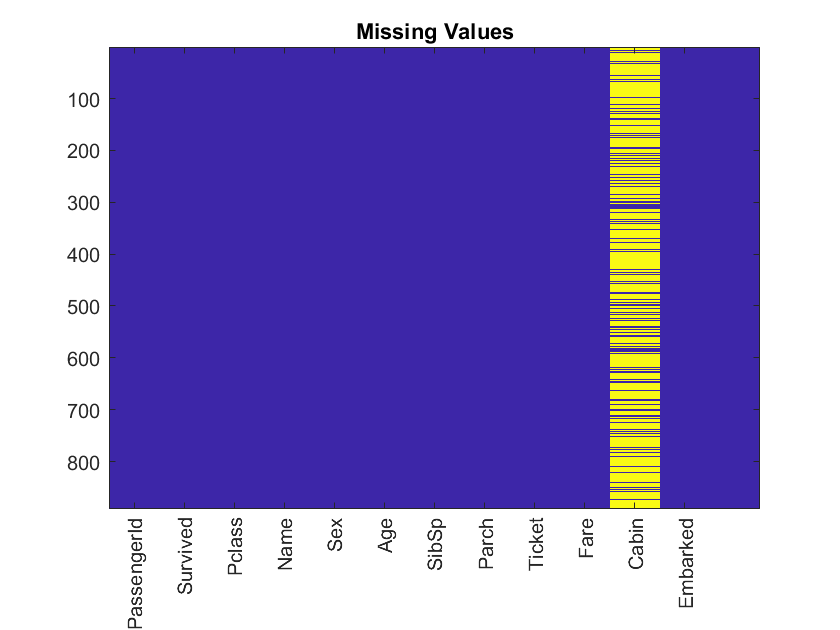

%%Set fares = 0 to NotANumber
Train.Fare(Train.Fare == 0) = NaN;      % treat 0 fare as NaN
Test.Fare(Test.Fare == 0) = NaN;        % treat 0 fare as NaN
vars = Train.Properties.VariableNames;  % extract column names

figure
imagesc(ismissing(Train))
ax = gca;
ax.XTick = 1:12;
ax.XTickLabel = vars;
ax.XTickLabelRotation = 90;
title('Missing Values')


%%Set ages not avaible to avg
avgAge = nanmean(Train.Age)             % get average age

avgAge = 29.6991

Train.Age(isnan(Train.Age)) = avgAge;   % replace NaN with the average
Test.Age(isnan(Test.Age)) = avgAge;     % replace NaN with the average

%%Set unknon fares to same as class members
fare = grpstats(Train(:,{'Pclass','Fare'}),'Pclass');   % get class average
disp(fare)

         Pclass    GroupCount    mean_Fare
         ______    __________    _________

    1      1          216         86.149  
    2      2          184         21.359  
    3      3          491         13.788  



for i = 1:height(fare) % for each |Pclass|
    % apply the class average to missing values
    Train.Fare(Train.Pclass == i & isnan(Train.Fare)) = fare.mean_Fare(i);
    Test.Fare(Test.Pclass == i & isnan(Test.Fare)) = fare.mean_Fare(i);
end

%%Handle cabin
% tokenize the text string by white space
train_cabins = cellfun(@strsplit, Train.Cabin, 'UniformOutput', false);
test_cabins = cellfun(@strsplit, Test.Cabin, 'UniformOutput', false);

% count the number of tokens
Train.nCabins = cellfun(@length, train_cabins);
Test.nCabins = cellfun(@length, test_cabins);

% deal with exceptions - only the first class people had multiple cabins
Train.nCabins(Train.Pclass ~= 1 & Train.nCabins > 1,:) = 1;
Test.nCabins(Test.Pclass ~= 1 & Test.nCabins > 1,:) = 1;

% if |Cabin| is empty, then |nCabins| should be 0
Train.nCabins(cellfun(@isempty, Train.Cabin)) = 0;
Test.nCabins(cellfun(@isempty, Test.Cabin)) = 0;

%%We dont know where some people embarked, so we assume the embarked in the
%%most frequent one
% get most frequent value
freqVal = mode(Train.Embarked);

% apply it to missling value
Train.Embarked(isundefined(Train.Embarked)) = freqVal;
Test.Embarked(isundefined(Test.Embarked)) = freqVal;

% convert the data type from categorical to double
Train.Embarked = double(Train.Embarked);
Test.Embarked = double(Test.Embarked);

%Convernt gender to number
Train.Sex = double(Train.Sex);
Test.Sex = double(Test.Sex);

%%Remove non relevant information
Train(:,{'Name','Ticket','Cabin'}) = [];
Test(:,{'Name','Ticket','Cabin'}) = [];


Visualize Data

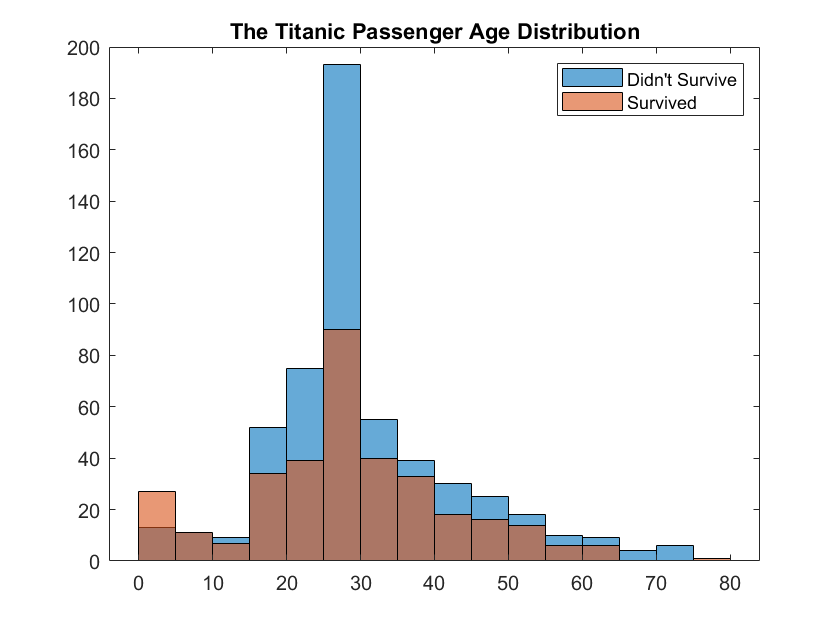

figure
histogram(Train.Age(Train.Survived == 0))   % age histogram of non-survivers
hold on
histogram(Train.Age(Train.Survived == 1))   % age histogram of survivers
hold off
legend('Didn''t Survive', 'Survived')
title('The Titanic Passenger Age Distribution')